Quadrature weights and points for a square


$$~$$


### Syntax                                                                                                                                                                                                                                                                                                                                                                                                                                                                     

Q = quadsquare(d)

Qs = struct with fields:
        Points: [9×2 double]
       Weights: [9×1 double]
    Properties: [1×1 struct]


Q = quadsquare(d,Name,Value)


$$~$$


### Description                                                                                                                                                                                                                                                                                                                                                                                                                                                                  

`Q = ``quadsquare``(d)` returns the weights and points of a Gauss–Legendre product rule of degree `d `for numerically integrating over the square domain $S=[-1,1]\times[-1,1]$. The output is stored as a structure `Q` with the following fields:

- `Q.Points =` the `n` quadrature points in an array of size `n×2`, where `Q.Points(:,1)` and `Q.Points(:,2)` are the `x` and `y` coordinates, respectively.

- `Q.Weights` = the corresponding quadrature weights stored in a column vector of length `n`.

- `Q.Properties` = contains (sub)fields describing the `.Degree` (the input value `d`), the `.Type` (see description below) and the` .Domain` of integration of the quadrature rule.

`Q = ``quadsquare``(d,Name,Value)` same as above but with additional control over the type of rules returned. Options include specification of the following `Name-Value` pair arguments: 

`'Type'` — Type of quadrature rule

`'productLegendre'` (default) │`'productLobatto'` │ `'nonproduct'`

The type of quadrature rule may be specified as `'productLegendre'` (the default), in which case the points and weights of a Gauss–Legendre product rule are returned, as `'productLobatto'`, in which case the points and weights of a Gauss–Lobatto product rule are returned, or as `'nonproduct'`. Product rules can be of arbitrary degree, while nonproduct rules are currently available up to degree 21.

The following additional `Name-Value` pairs are available for nonproduct rules:

`'Symmetry'` — Symmetry of the quadrature rule

`'full' `(default) │` 'allowAsymmetric'`

The `'full' `(default) value requires the quadrature rule to be fully symmetric. The value 'allowAsymmetric' allows asymmetric quadrature rules of lower point count than the full symmetry rules to be returned when available. (Note: Some quadrature rules possess so-called partial symmetry, though no distinction is made here between asymmetric and partially symmetric rules, i.e., a rule is classified as either fully symmetric or asymmetric.)

`'Weights'` — Quadrature weight conditions

`'positive'` (default) │ `'allowNegative'`

The `'postive' `(default) value requires all quadrature weights to be positive. The value `'allowNegative'` allows quadrature rules with negative weight(s) of lower point count than the positive weight rules to be returned when available.

`'Points' `— Location of quadrature points

`'inside' `(default) |` 'allowOutside'`

The `'inside'` (default) requires all points to be inside the domain. The value `'allowOutside'` allows quadrature rules with point(s) outside the domain of lower point count than the quadrature rules with all points inside to be returned when available.

Note: The default `Name-Value` pairs for nonproduct rules are set such that the minimal-point, fully symmetric so-called **PI** rule (that is, all weights are **P**ositive and all points are **I**nside the domain) of degree `d` is returned. Fully symmetric PI rules are generally preferred among practitioners.

### Examples                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

**Example 1 **$-$**  The derivation of product rules for the square**

The simplest way to construct a quadrature rule over the square is to take a product of one-dimesional Gauss quadrature rules in each coordinate direction $x$,$y.$ This is the default type of quadrature rule returned using the `quadsquare` function. For example,  a degree 5 (Gauss–Legendre) product quadrature rule for the square is obtained by

Qs = quadsquare(5)

ans =    -0.7746   -0.7746
   -0.7746         0
   -0.7746    0.7746
         0   -0.7746
         0         0
         0    0.7746
    0.7746   -0.7746
    0.7746         0
    0.7746    0.7746


which has $3^2=9$ points with coordinates

Qs.Points

These points are obtained within the `quadsquare` function by simply taking a [Cartesian product](https://en.wikipedia.org/wiki/Cartesian_product) of two one-dimensional, 3-point Gauss–Legendre rules, which can be obtained in MATLAB® using the `meshgrid` function, i.e., 

Q1d = quadGaussLegendre(3);
[X,Y] = meshgrid(Q1d.Points,Q1d.Points);

ans =    -0.7746   -0.7746
   -0.7746         0
   -0.7746    0.7746
         0   -0.7746
         0         0
         0    0.7746
    0.7746   -0.7746
    0.7746         0
    0.7746    0.7746


[X(:),Y(:)]

Gauss–Lobatto product rules can also be obtained using the `quadsquare` function by specifying the following `Name-Value` pair

Qs = quadsquare(5,'Type','productLobatto')

Qs = struct with fields:
        Points: [16×2 double]
       Weights: [16×1 double]
    Properties: [1×1 struct]


Although this degree 5 rule has $4^2=16$ points instead of 9, it may be preferred in situations where integrals over the boundaries of the square also have to be computed, which require quadrature points on the edges of the square, i.e.,

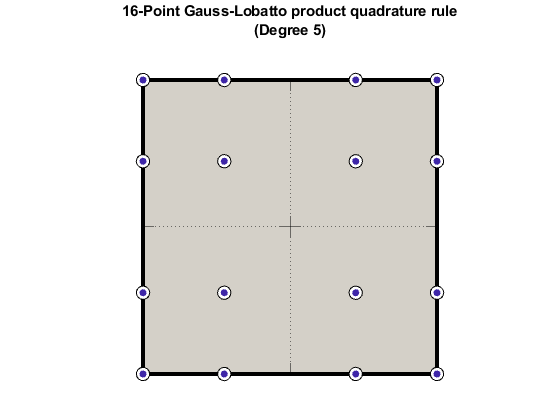

quadplot(Qs)

**Example 2 **$-$**  A disadvantage of using product quadrature rules for the square**

One disadvantage of using product quadrature rules over the square is the use of a greater number of points than necessary for a given degree. For example, consider the bipolynomial of total degree 6


$$P(x,y) = 7x^6 + 2x^3y^2 + 7y^3$$


which we define as an anonymous function

P = @(x,y) 7*x.^6 + 2*x.^3.*y.^2 + 7*y.^3;

The exact (double) integral of this function over the square is


$$\displaystyle \int_{-1}^{1} \int_{-1}^{1} P(x,y)\,\mathrm {d} x=4.$$


This can be computed exactly using a degree 6 product rule, i.e.,

Qp = quadsquare(6)

Qp = struct with fields:
        Points: [16×2 double]
       Weights: [16×1 double]
    Properties: [1×1 struct]


dot(Qp.Weights,P(Qp.Points(:,1),Qp.Points(:,2)))

ans = 4.0000

which uses 16 points, or a degree 6 (not fully symmetric) nonproduct rule

Qnp = quadsquare(6,'Type','nonproduct','Symmetry','allowAsymmetric')

Qnp = struct with fields:
        Points: [10×2 double]
       Weights: [10×1 double]
    Properties: [1×1 struct]


dot(Qnp.Weights,P(Qnp.Points(:,1),Qnp.Points(:,2)))

ans = 4.0000

which uses only 10 points $-$ the fewest possible number of points for a degree 6 rule for the square (note that this rule was obtained by allowing for asymmetry in the symmetry `Name-Value` pair). A plot of this particular nonproduct rule obtained using the `quadplot` function reveals the points are not fully symmetric (though they have reflection symmetry about the $y$ axis)

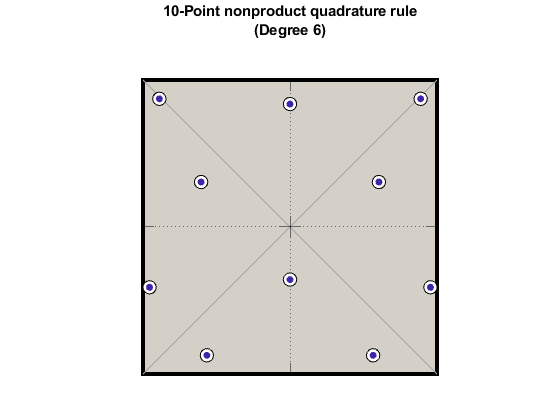

figure
quadplot(Qnp)

Many finite element practioners prefer fully symmetric rules. A fully symmetric degree 6 nonproduct rule can be obtained by removing the symmetry `Name-Value` pair, i.e.,

Qnp = quadsquare(6,'Type','nonproduct')

Qnp = struct with fields:
        Points: [12×2 double]
       Weights: [12×1 double]
    Properties: [1×1 struct]


Although this rule has 2 additional points, it does have full symmetry, which is easily observed using the [quadplot](http://u.osu.edu/kubatko.3/codes_and_software/quadtools/quadplot/) function:

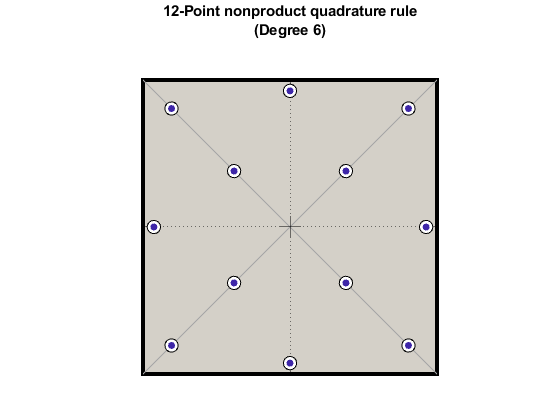

figure
quadplot(Qnp)

As noted above, the default `Name-Value` pairs for nonproduct rules are set such that the minimal-point, fully symmetric so-called **PI** rule (that is, all weights are **P**ositive and all points are **I**nside the domain) of degree $d$ is returned. 

#### *This function is part of........*